%global N J tmax Nt NA NV phi delta loop method;

N=400;          %粒子链总长度
J=100;          %相互作用强度
tmax=3;       %模拟时间
Nt=1000;         %时间采样数
NA=100;         %波包初态中心位置
NV=200;         %散射粒子位置
phi=pi/2;
delta=30;      %波包半宽
loop=true;
method='ode';
V=1*J;

psi0 = GaussianState(N, NA, phi, delta);
H = Hamilton(N, J, loop);
for ii = (N-50):N
    H(ii,ii) = -1*(abs(ii-N+50))*1i;
end
for ii = 1:50
    H(ii,ii) = -1*(abs(ii-50))*1i;
end

H(NV,NV) = V;
[VEC,D] = eig(H);
opts = odeset('Reltol',1e-8,'AbsTol',1e-10);
tic
[t,psi] = psicalc(H, psi0, tmax, method,opts);
toc

历时 1.705062 秒。


H(NV,NV) = V;
[VEC,D] = eig(H);
tic
[t1,psi1] = psicalc(H, psi0, tmax, 'ode', opts);
toc

历时 1.605665 秒。


tic
[t2,psi2] = psicalc(H, psi0, tmax, 'expm', 20);
toc

历时 1.026761 秒。


tic
[t3,psi3] = psicalc(H, psi0, tmax, 'eig', 20, VEC, D);
toc

历时 0.210202 秒。


p1 = vecnorm(psi1(:, NV:N), 2, 2); %右边一半的波函数概率总和
T1 = max(p1)

T1 =    0.894287795448543


p2 = vecnorm(psi2(:, NV:N), 2, 2); %右边一半的波函数概率总和
T2 = max(p1)

T2 =    0.894287795448543


p3 = vecnorm(psi3(:, NV:N), 2, 2); %右边一半的波函数概率总和
T3 = max(p1)

T3 =    0.894287795448543


Vs = (0:0.1:5)*J;
tic
parfor ii = 1:length(Vs)
    Hii=H;                  %parfor不能修改共用变量，所以要每个线程复制一份分别修改
    Hii(NV, NV) = Vs(ii);
    [VEC, D] = eig(Hii);
    [t, psi] = psicalc(H, psi0, tmax, 'eig', 10, VEC, D);
    T(ii) = max(vecnorm(psi(:, NV:N), 2, 2))^2;
end
toc

历时 6.322619 秒。


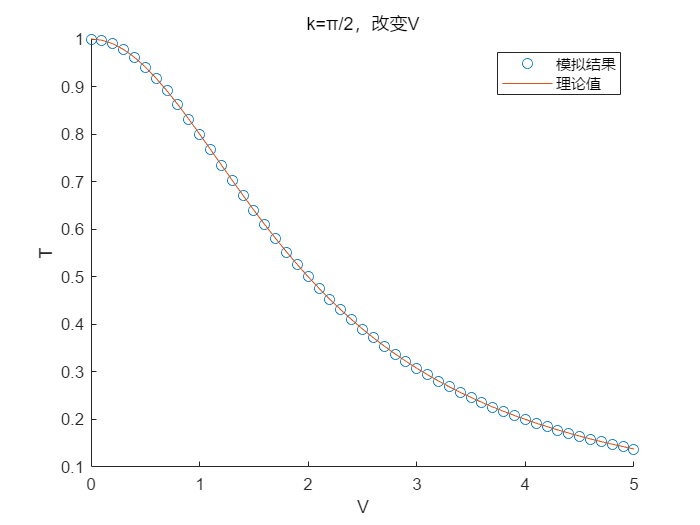

scatter(Vs / J, T)
hold on
plot(Vs / J, 4 ./ (4 + (Vs / J).^2))
hold off
legend('模拟结果', '理论值')
xlabel('V')
ylabel('T')
title('k=\pi/2，改变V')

phis = (0:0.05:1) * pi;
H(NV, NV) = 2 * J;
[VEC, D] = eig(H);
tic
T = zeros(1, length(phis));
parfor ii = 1:length(phis)
    psi0 = GaussianState(N, NA, phis(ii), delta);
    [~, psi] = psicalc(H, psi0, tmax, 'eig', 20, VEC, D);
    T(ii) = max(vecnorm(psi(:, NV:N), 2, 2))^2;
end
toc

历时 3.228834 秒。


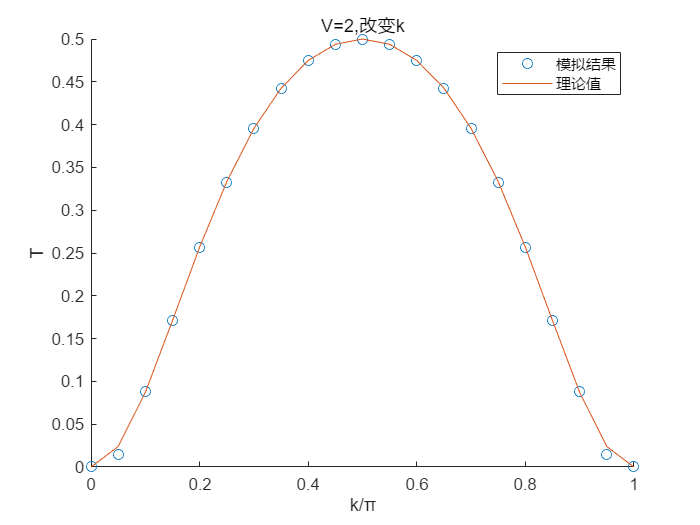

scatter(phis / pi, T)
hold on
plot(phis / pi, (4 * sin(phis) .^ 2 )./ (4 * sin(phis) .^ 2 + 2^2))
hold off
legend('模拟结果', '理论值')
xlabel('k/\pi')
ylabel('T')
title('V=2,改变k')

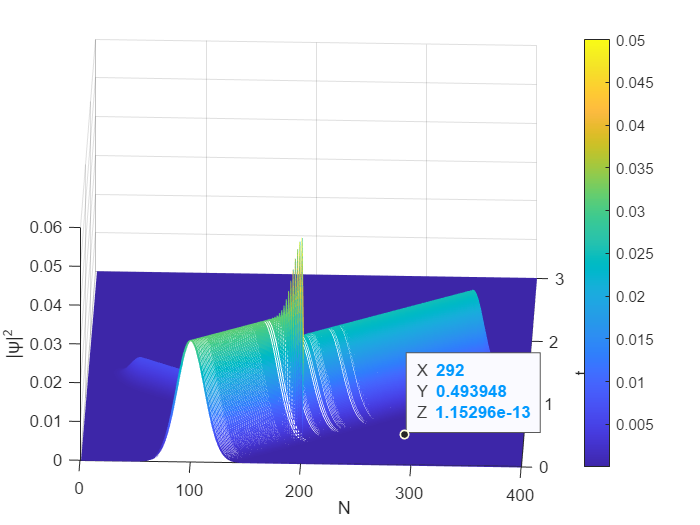

%ode方法数据太多，画图容易卡，抽样一部分用来画图即可
if strcmp(method,'ode')
    dt = floor( length(t) / Nt );
    tplot = t(1:dt:end);
    psiplot = psi(1:dt:end,:);
else
    tplot = t;
    psiplot = psi;
end

plotpsi(psiplot,tplot,N)

function [t,psi] = psicalc(H,psi0,tmax,method,varargin)
if strcmp(method,'ode')
    if nargin == 5
        opts = varargin{1};
        tspan = [0, tmax];
        [t, psi] = ode113(@(t, psi) -1i * H * psi, tspan, psi0, opts);
    else
        tspan = [0, tmax];
        [t, psi] = ode113(@(t, psi) -1i * H * psi, tspan, psi0);
    end
elseif strcmp(method,'expm')
    Nt = varargin{1};
    [t,psi] = psicalc_expm(H,psi0,tmax,Nt);
elseif strcmp(method,'eig')
    Nt = varargin{1};
    VEC = varargin{2};
    D = varargin{3};
    [t,psi] = psicalc_eig(VEC,D,psi0,tmax,Nt);
end
end



